# Speech Emotion Recognition based on multi corpus

#                                                 --------- stage 2 Rebuild exp 1

%-----------adjust--------that-------------------------
predictors_train = [predictors_33333_SAVEE;predictors_33333_RAVDESS;predictors_33333_EMODB];
response_train = [response_33333_SAVEE;response_33333_RAVDESS;response_33333_EMODB];
%------------------------------------------------------
mdl = fitcknn(...
    predictors_train, ...
    response_train, ...
    'Distance', 'Euclidean', ...
    'Exponent', [], ...
    'NumNeighbors', 5, ...
    'DistanceWeight', 'SquaredInverse', ...
    'Standardize', false, ...
    'ClassNames', categorical({'anger'; 'disgust'; 'fear'; 'happiness'; 'neutral'; 'sadness'}));

- Test

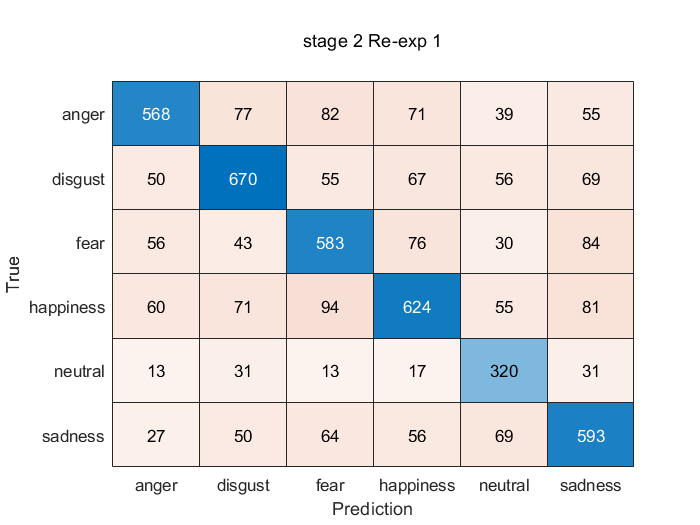

%-----------adjust--------that-------------------------
validationPredictors = predictors_test_RAVDESS;
validationResponse = response_test_RAVDESS;
%------------------------------------------------------
[validationPredictions, validationScores] = predict(mdl, validationPredictors);

correctPredictions = (validationPredictions == validationResponse);
isMissing = ismissing(validationResponse);
correctPredictions = correctPredictions(~isMissing);
validationAccuracy = sum(correctPredictions)/length(correctPredictions);

figure(1);
confusion_matrix1 = confusionchart(validationResponse,validationPredictions);
confusion_matrix1.Title = {'';'stage 2 Re-exp 1';''};
confusion_matrix1.YLabel = 'True';
confusion_matrix1.XLabel = 'Prediction';

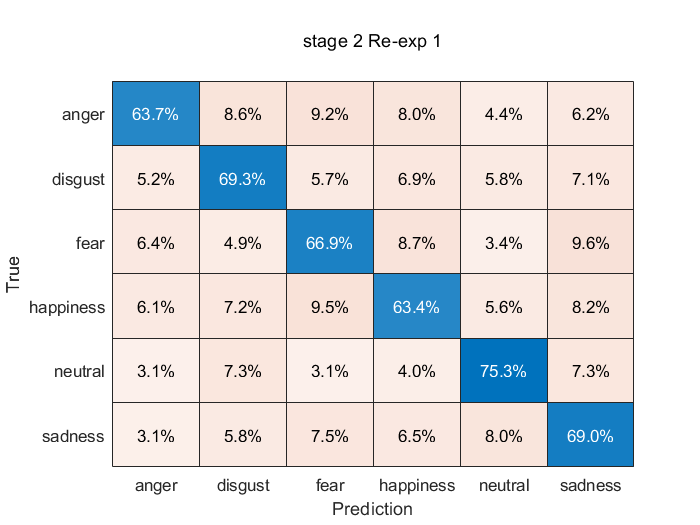


figure(2);
confusion_matrix2 = confusionchart(validationResponse,validationPredictions);
confusion_matrix2.Title = {'';'stage 2 Re-exp 1';''};
confusion_matrix2.YLabel = 'True';
confusion_matrix2.XLabel = 'Prediction';
% confusion_matrix2.RowSummary = 'row-normalized';
confusion_matrix2.Normalization = 'row-normalized';


validationAccuracy

validationAccuracy = 0.6716

Clear other vars

clearvars -except response_33333_SAVEE response_50000_SAVEE response_100000_SAVEE ...
    predictors_33333_SAVEE predictors_50000_SAVEE predictors_100000_SAVEE ...
    response_33333_EMODB response_50000_EMODB response_100000_EMODB ...
    predictors_33333_EMODB predictors_50000_EMODB predictors_100000_EMODB ...
    response_33333_RAVDESS response_50000_RAVDESS response_100000_RAVDESS ...
    predictors_33333_RAVDESS predictors_50000_RAVDESS predictors_100000_RAVDESS ...
    response_test_SAVEE response_test_RAVDESS response_test_EMODB ...
    predictors_test_SAVEE predictors_test_RAVDESS predictors_test_EMODB;